# Calculate Joint Angles using Inverse Kinematics and Check with Rigid Body Tree

Here we calculate the joint angles from the left and right foot trajectories. 

We use an analytic solution of inverse kinematics for the leg based on [Closed-Form Inverse Kinematic Joint Solution for Humanoid Robots](https://ieeexplore.ieee.org/document/5649842) by Ali et. al. The function for inverse kinematics is called [`invKinBody2Foot`](matlab: edit invKinBody2Foot). The input to the simulation will be the feet transform matrix that contain position and orientation information. 

Finidng the analytic solution to the inverse kinematics requires deriving an expression based on the forward kinematics, which can be time consuming, difficult, and even impossible for some robot geometries and/or constraints. In that case, you may want to consider using the optimization-based [`inverseKinematics`](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html) solver from Robotics System Toolbox. Although it is slower than the analytical solution, it can be applied to arbitrary kinematic chains with constraints. 

*Copyright 2019 The MathWorks, Inc.*

animateOn = true; 
speedupfactor = 12; % animation speed up 

% load default parameters if previous script wasn't run
if ~exist('footinfos','var')
    load('not_defaultfootinfos.mat')
end
% Assuming constraint bounds are already imported
% NOTE: make sure parameters match in inverse kinematics function 


% model = importrobot("robot.slx", "ConvertJoints", "convert-to-fixed");
% save('not_defaultmodel.mat', 'model')

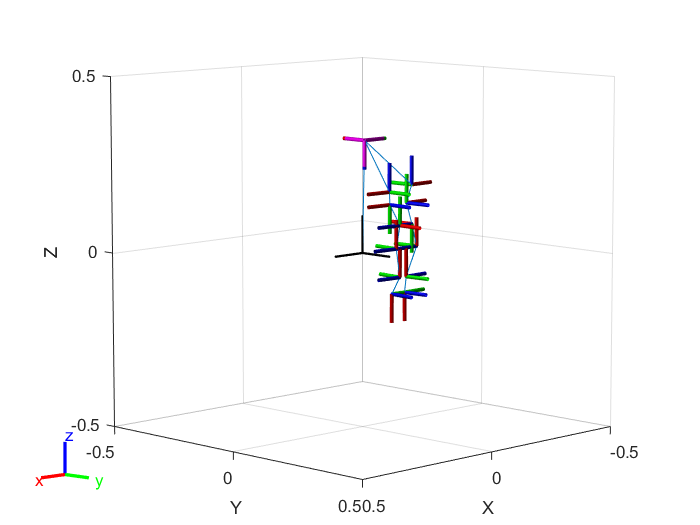


if ~exist('model','var')
    load('not_defaultmodel.mat')
end
initConfig = model.homeConfiguration;
show(model, initConfig); 

model

model =   rigidBodyTree with properties:

     NumBodies: 13
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Body01'  'Body02'  'Body03'  'Body04'  'Body05'  'Body06'  'Body07'  'Body08'  'Body09'  'Body10'  'Body11'  'Body12'  'Body13'}
      BaseName: 'Base'
       Gravity: [0 0 -9.8066]
    DataFormat: 'struct'


showdetails(model)

--------------------
Robot: (13 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        Body01        Joint01          fixed              Base(0)   Body02(2)  Body08(8)  
   2        Body02        Joint02       revolute            Body01(1)   Body03(3)  
   3        Body03        Joint03       revolute            Body02(2)   Body04(4)  
   4        Body04        Joint04       revolute            Body03(3)   Body05(5)  
   5        Body05        Joint05       revolute            Body04(4)   Body06(6)  
   6        Body06        Joint06       revolute            Body05(5)   Body07(7)  
   7        Body07        Joint07       revolute            Body06(6)   
   8        Body08        Joint08       revolute            Body01(1)   Body09(9)  
   9        Body09        Joint09       revolute            Body08(8)   Body10(10)  
  10        Body10      

gik = generalizedInverseKinematics('RigidBodyTree', model, 'ConstraintInputs', {'pose','pose'})

gik =   generalizedInverseKinematics with properties:

      NumConstraints: 2
    ConstraintInputs: {'pose'  'pose'}
       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


gik.SolverParameters.AllowRandomRestart = false;
initialguess = model.homeConfiguration;

Test

n = [0;  0; -1]; % x
s = [-1; 0; 0];  % y
a = [0;  1; 0];  % z
R = [n s a]; 
% Getting the first destination
% each step is a new index
% only get indices 1, 3, 5 since 2, 4, 6 is just a mirror of that
stateL = footinfos{1}.footleft([1 3 5],:); 
pL = stateL(:, 1)

pL =    -0.0450
         0
   -0.4050


transmatL =  [R     pL; 
                    [0 0 0 1]];
leftFoot = constraintPoseTarget('Body13', 'TargetTransform', transmatL)

leftFoot =   constraintPoseTarget with properties:

             EndEffector: 'Body13'
           ReferenceBody: ''
         TargetTransform: [4×4 double]
    OrientationTolerance: 0
       PositionTolerance: 0
                 Weights: [1 1]


stateR = footinfos{1}.footright([1 3 5],:); 
pR = stateR(:, 1)

pR =     0.0450
         0
   -0.4050


transmatR =  [R     pR; [0 0 0 1]];
rightFoot = constraintPoseTarget('Body07', 'TargetTransform', transmatR)

rightFoot =   constraintPoseTarget with properties:

             EndEffector: 'Body07'
           ReferenceBody: ''
         TargetTransform: [4×4 double]
    OrientationTolerance: 0
       PositionTolerance: 0
                 Weights: [1 1]


[configSol,solInfo] = gik(initialguess, leftFoot, rightFoot)

configSol = 1×12 struct array with fields:
    JointName
    JointPosition


solInfo = struct with fields:
              Iterations: 42
       NumRandomRestarts: 0
    ConstraintViolations: [1×2 struct]
                ExitFlag: 1
                  Status: 'best available'


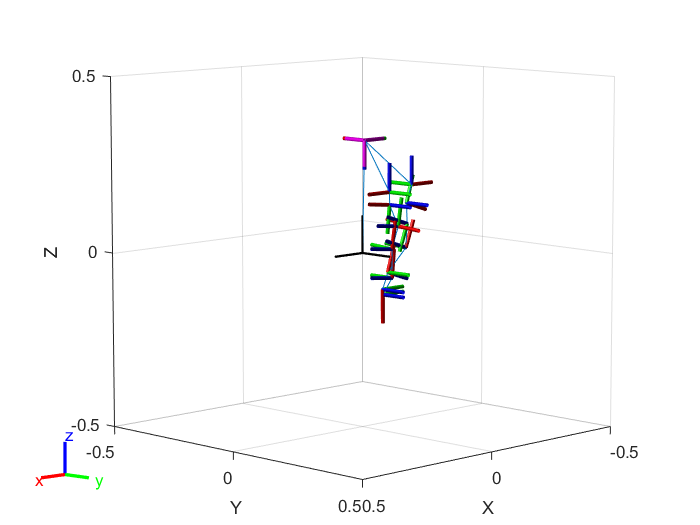

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(model, configSol)

solInfo

solInfo = struct with fields:
              Iterations: 42
       NumRandomRestarts: 0
    ConstraintViolations: [1×2 struct]
                ExitFlag: 1
                  Status: 'best available'


% dhparams
desconfig = model.homeConfiguration; 
desconfig

desconfig = 1×12 struct array with fields:
    JointName
    JointPosition


configSol

configSol = 1×12 struct array with fields:
    JointName
    JointPosition


## Show the Rigid Body Tree

% showdetails(robot)
hFig = figure; 
hFig.Visible = 'on'; 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 0.5 0.5]; 

model.homeConfiguration

ans = 1×12 struct array with fields:
    JointName
    JointPosition


## Animate Joint Trajectory

Note that feet orientation is always normal to the ground. Also note the Z vector of the end effector is pointed toward the ground. 

currguess = initialguess

currguess = 1×12 struct array with fields:
    JointName
    JointPosition


     1

     2

     3

     4



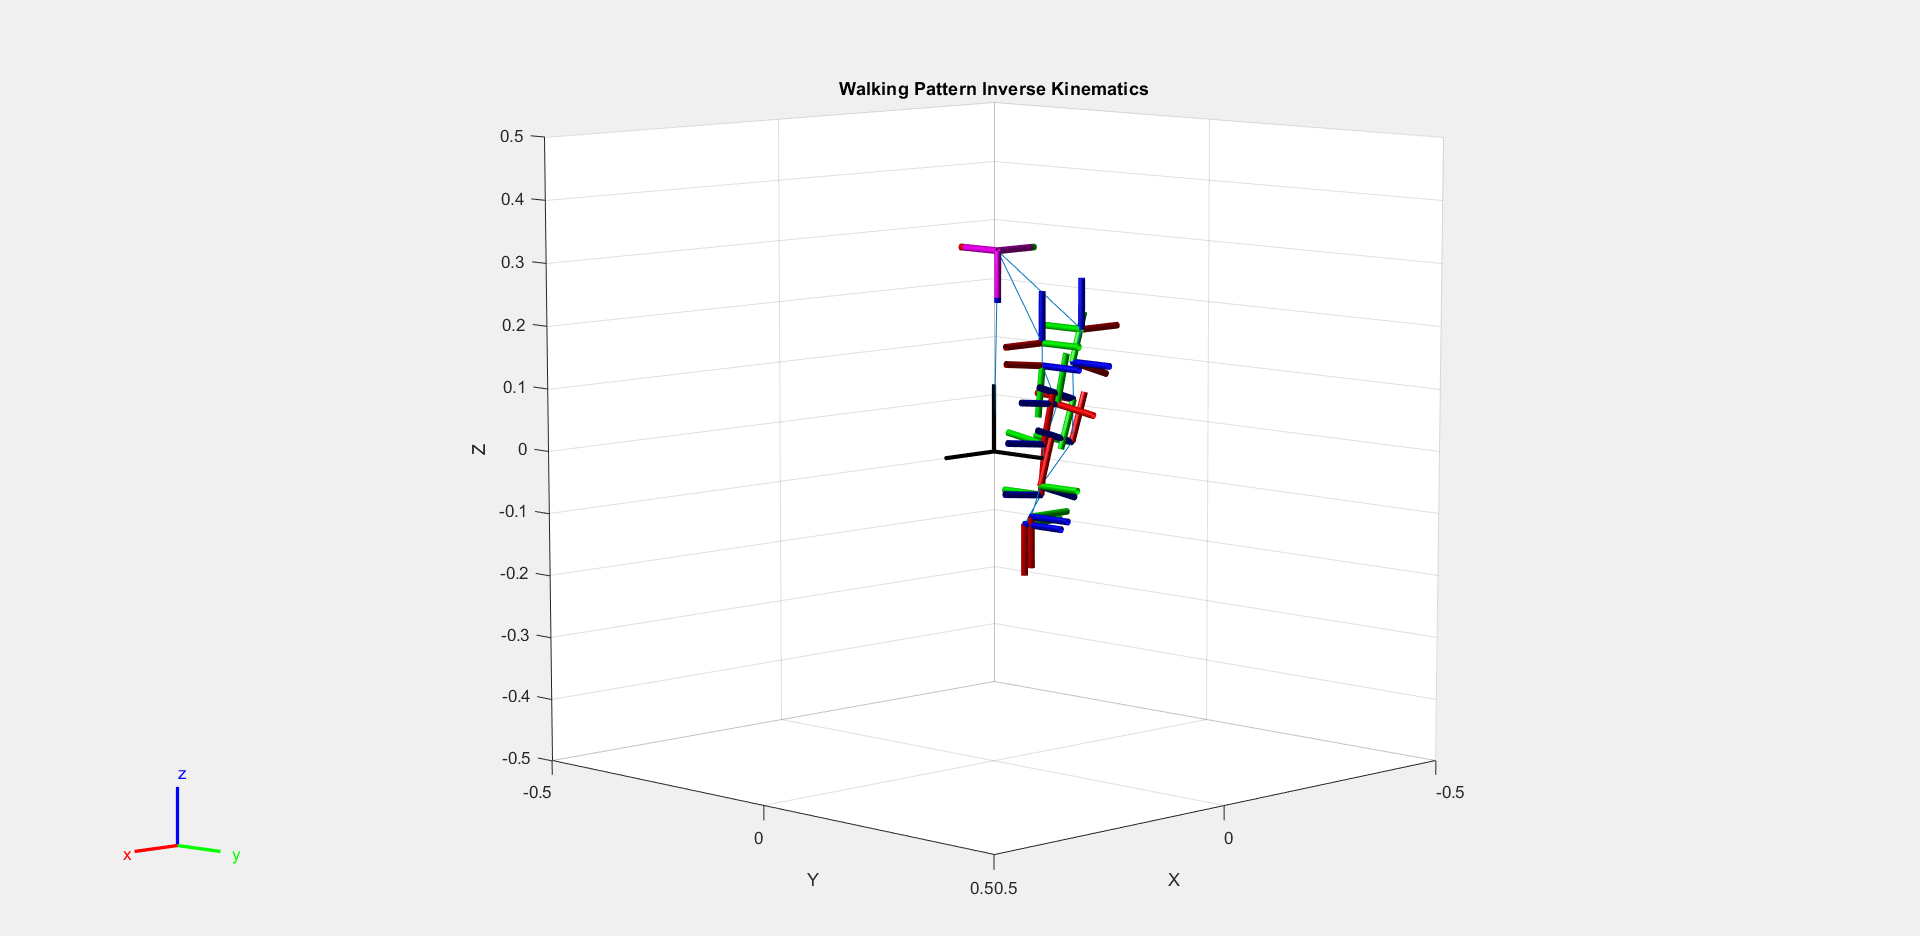

     5

     6

     7

     8



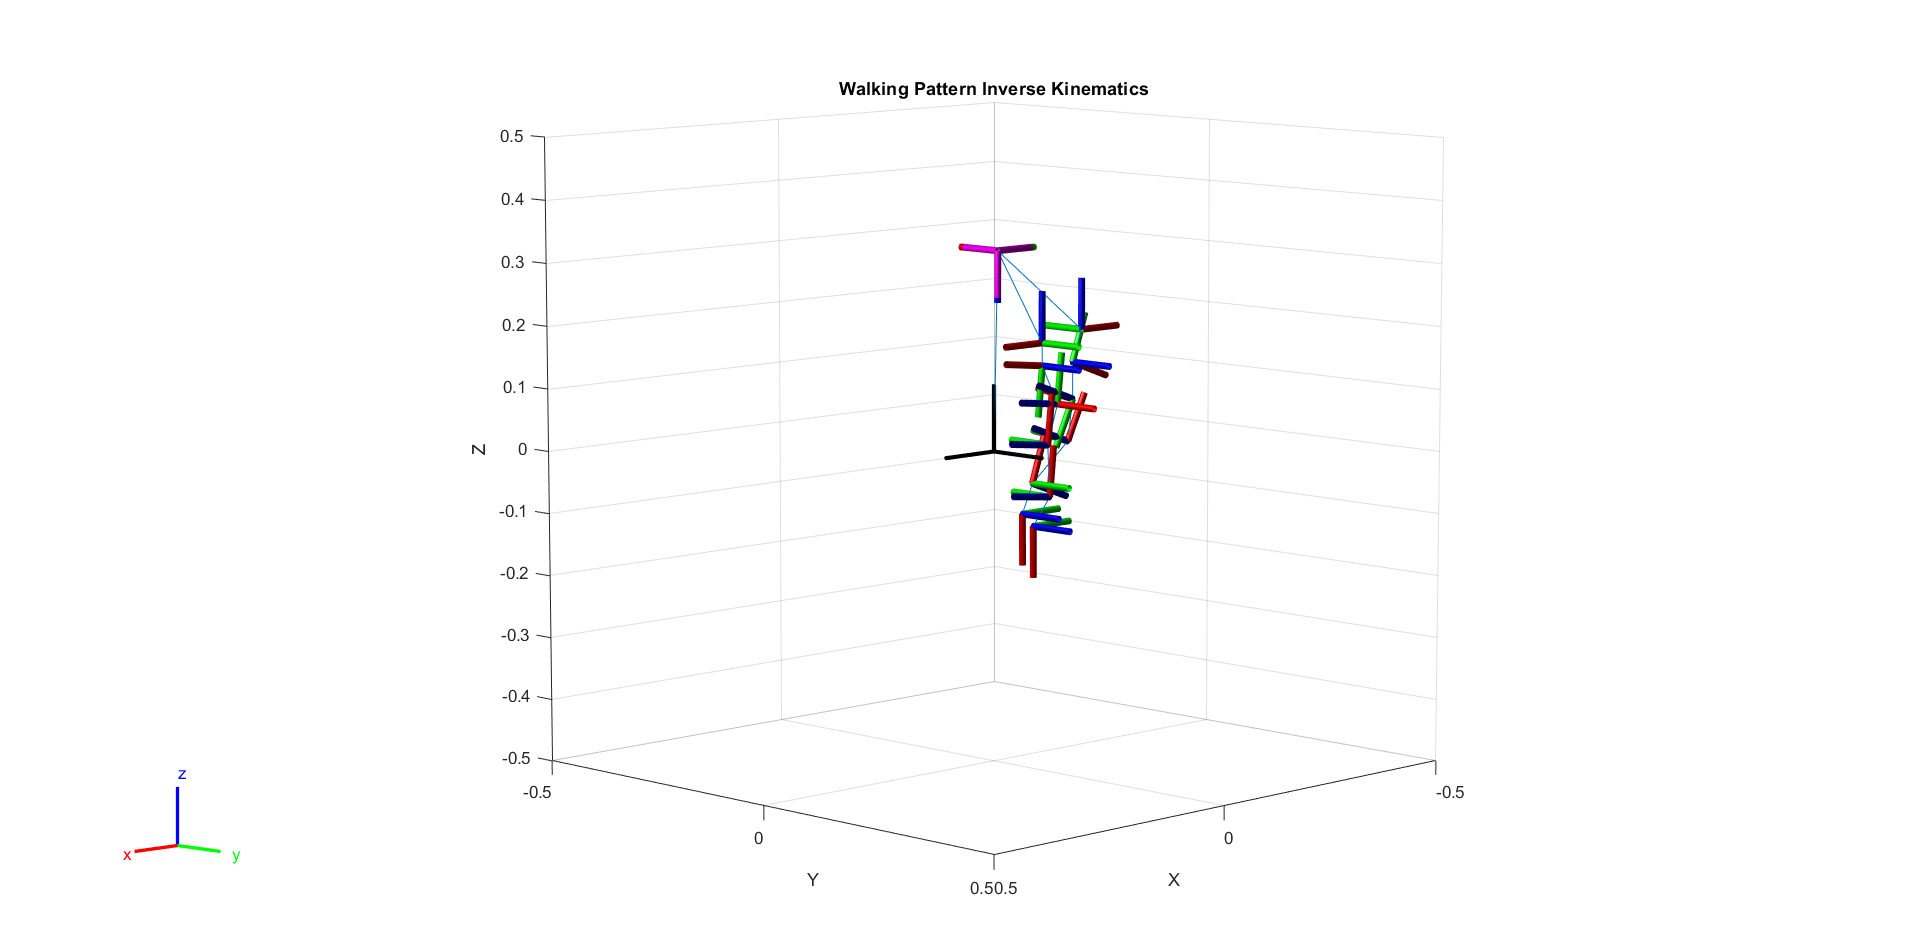

tic
    for sIdx = 1:length(footinfos)
        disp(sIdx)
        % Extract X Y Z position states (indices 1, 3, and 5)
        stateL = footinfos{sIdx}.footleft([1 3 5],:); 
        stateR = footinfos{sIdx}.footright([1 3 5],:); 
        
        % Initialize matrices
        numIdx = size(stateL,2); 
        jointsLeft = zeros(6,numIdx); 
        jointsRight = zeros(6,numIdx); 
        transMatLeft = zeros(4,4,numIdx); 
        transMatRight = zeros(4,4,numIdx); 
        
        % Skip some intermediate steps when visualizing 
        for idx = 1:numIdx
            % Get Left joints
            p = stateL(:,idx); 
            transmat =  [R     p; 
                        [0 0 0 1]];
            leftFoot = constraintPoseTarget('Body13', 'TargetTransform', transmat);
            transMatLeft(:,:,idx) = transmat; 
            
            % Get Right joints
            p = stateR(:,idx); 
            transmat =  [R     p; 
                        [0 0 0 1]];
            rightFoot = constraintPoseTarget('Body07', 'TargetTransform', transmat);
            transMatRight(:,:,idx) = transmat; 
            [currguess,solInfo] = gik(currguess, leftFoot, rightFoot);
            % Animate
            if animateOn
                if rem(idx,speedupfactor) == 0
                    show(model, currguess, 'PreservePlot', false);
                    title('Walking Pattern Inverse Kinematics');
                    pause(0.001);
                end 
            end
        end
        % save joints info  
        footinfos{sIdx}.transmatleft = transMatLeft; 
        footinfos{sIdx}.transmatright = transMatRight; 
    end

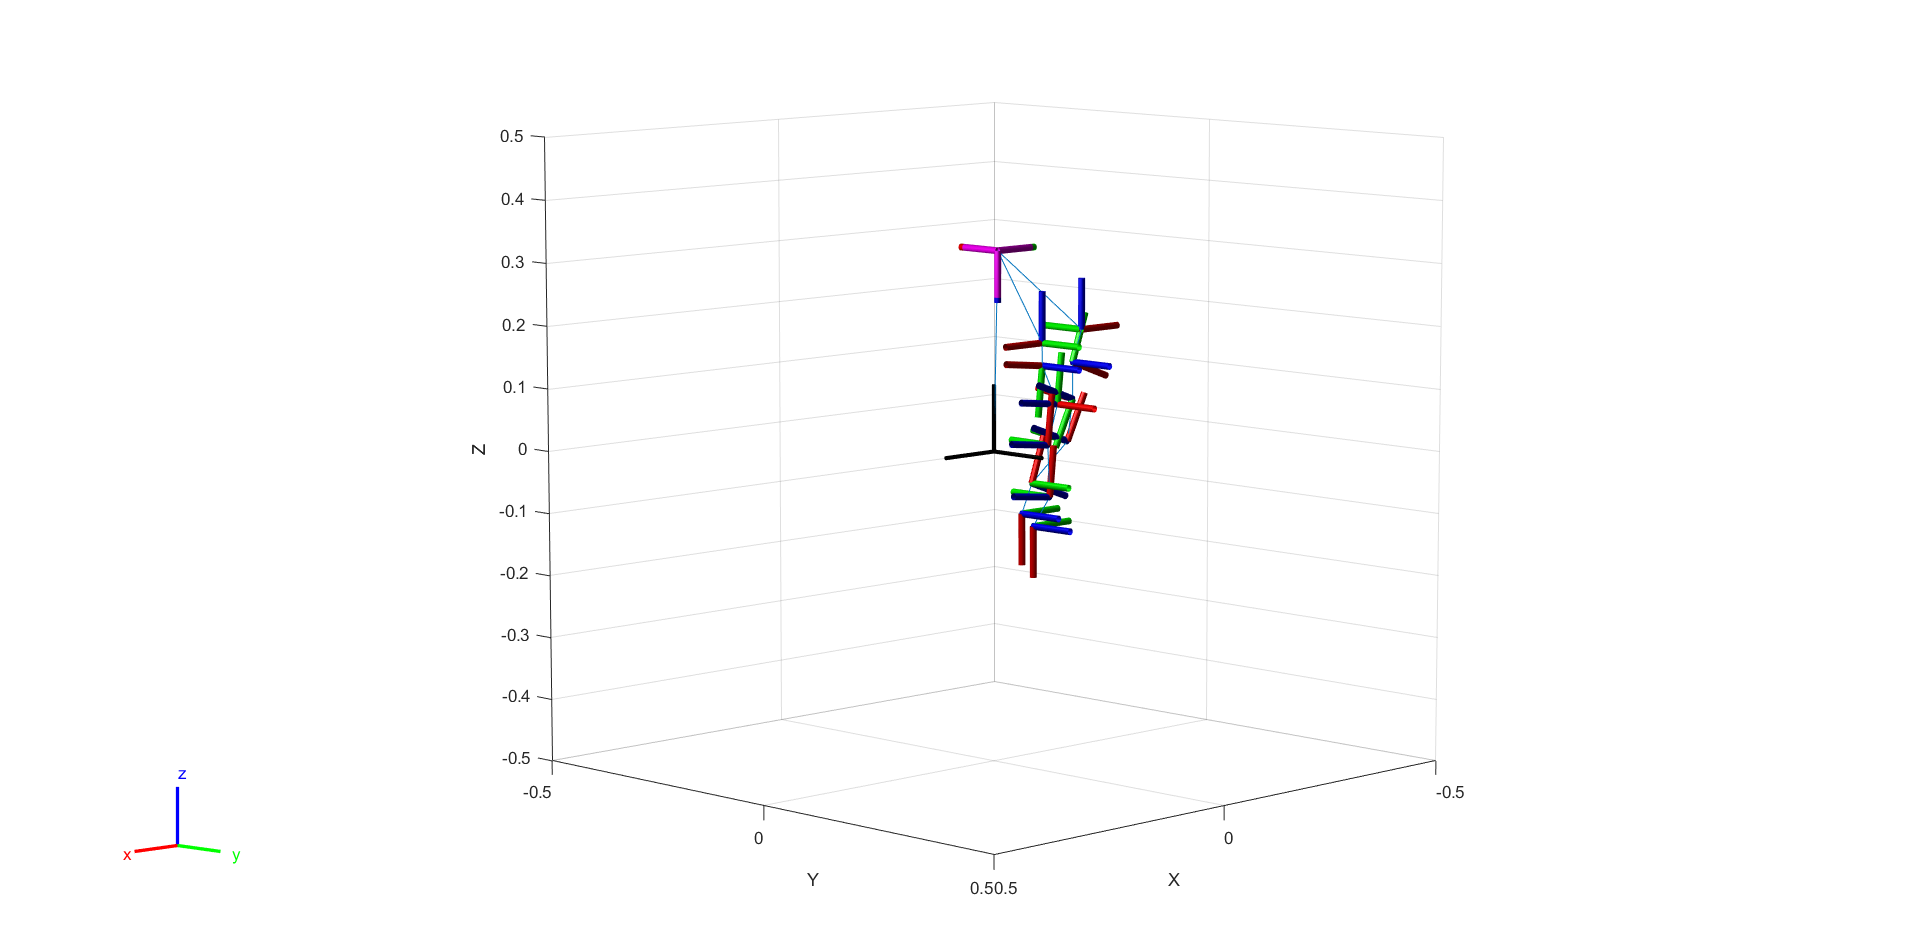

    show(model, currguess, 'PreservePlot', false);

toc

Elapsed time is 55.741795 seconds.


## Create Simulation Input (End Effector)

The two variables used inside the simulation are end effector position and orientation information for the left leg and the right leg. This end effector position and orientation information is in the form of 4-by-4 transformation matrices. 

timeVec = footinfos{1}.timevec; 
transMatLeft = footinfos{1}.transmatleft; 
transMatRight = footinfos{1}.transmatright; 
    
siminL.time = timeVec;
siminL.signals.values = transMatLeft;
siminL.signals.dimensions = [4,4];

siminR.time = timeVec;
siminR.signals.values = transMatRight;
siminR.signals.dimensions = [4,4];

for idx = 2:length(footinfos)
    timeVec = footinfos{idx}.timevec;

    transMatLeft = footinfos{idx}.transmatleft; 
    transMatRight = footinfos{idx}.transmatright; 

    siminL.time = [siminL.time timeVec];
    siminL.signals.values = cat(3,siminL.signals.values, transMatLeft);

    siminR.time = [siminR.time timeVec];
    siminR.signals.values = cat(3,siminR.signals.values, transMatRight);
end

siminL

siminL = struct with fields:
       time: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 … ]
    signals: [1×1 struct]


siminR

siminR = struct with fields:
       time: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 … ]
    signals: [1×1 struct]


## Helper Functions

function updateJoints(model, anglesright, anglesleft)
    
    desconfig = model.homeConfiguration; 
    for idx = 1:length(anglesright)
        desconfig(idx).JointPosition = desconfig(idx).JointPosition+anglesright(idx);
    end 
%     desconfig(1).JointPosition = desconfig(1).JointPosition - pi;
%     desconfig(2).JointPosition = desconfig(2).JointPosition + pi/2; 
%     
%     desconfig(8).JointPosition = pi;
    for idx = 1:length(anglesleft)
%         display(idx+6)
        desconfig(idx+6).JointPosition = desconfig(idx+6).JointPosition+anglesleft(idx);
    end 
%     desconfig(7).JointPosition = desconfig(7).JointPosition - pi; 
%     desconfig(8).JointPosition = desconfig(8).JointPosition + pi/2; 
       
    % update graphics 
%     display(desconfig)
    show(model, desconfig, 'PreservePlot', false);
%     show(robot, desconfig)
    title('Walking Pattern Inverse Kinematics')
    pause(0.001)
end